**SYST 662 Team 1 Project**

**Questions**

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence? 

(Q2) What fraction of trips are re-routed due to road conditions?

**Notes**

<insert header notes here>

**Script:**

% Declare Answer Variables
Q1_predictive_routing_savings_value = " NOT"; % Replace with "" (empty string) if true
Q2_fraction_of_trips_rereouted_value = 0;

% Load Data Files
load EastCoast.mat
load Supporting_Data_Team_01.mat

% Set Up Simulation
% TODO all code here

## TUTORIAL CODE ONLY - remove after implementing our solution

### Computing times through the graph

The ITS problem requires computing travel times through the road network (graph).  The code below will compute the travel times for five random trips through the baseline graph.

% Define unit conversion
mins_per_hr = 60;
% Select start and stop points for tests
% Randomly selects 5 trips
trips = randi(numnodes(G),5,2); % numnodes(G) returns the # of nodes in the graph
for k=1:size(trips,1) % size(trips,1) returns the number of rows in the matrix
    % Get the names of the start and end points
    start_name = G.Nodes.Name(trips(k,1)); % Returns a cell array
    end_name   = G.Nodes.Name(trips(k,2)); % Returns a cell array
    fprintf('Trip %d : From [%s] to [%s]\n', ...
        k, start_name{1}, end_name{1});
end

Trip 1 : From [US58@+x292] to [US250/WV92@+X032(US250)]
Trip 2 : From [US219@WV/MD] to [US219@+X17]
Trip 3 : From [US60/KY1012] to [US15@NC/VA]
Trip 4 : From [US60/US219] to [US521/US17AltSum@BriChiRd]
Trip 5 : From [I-77(162A)/US422/OH8/OH87] to [US70@33rdSt]


% Change the graph weights to equal the travel time
% Note the use of vectorization to speed up the computation
G.Edges.Weight = G.Edges.Distance ./ G.Edges.Speed * mins_per_hr;
% Evaluate the trips using the baseline graph
for k=1:size(trips,1)  
    % Find the shortest path from start to end. Indicate all the 
    % Weights are positive to support a faster algorithm
    [path_nominal , t_nominal] = shortestpath(G,trips(k,1),trips(k,2),...
         'method','positive'); 
     
    % Get all the node IDs (numbers) for each node in the path
    node_ids = findnode(G,path_nominal);
    % Get all the edge IDs (numbers) for each edge in the path
    edge_ids = findedge(G, node_ids(1:end-1), node_ids(2:end));
    % Compute the distance of the path by summing the length of each edge
    nominal_distance = sum(G.Edges.Distance( edge_ids ) );
    % Compute the average speed along the path
    average_speed = mean(G.Edges.Speed( edge_ids ) );
    
    fprintf('Trip %2d - %6.2f miles, travel time = %6.2f mins, average speed = %6.2f\n', ...
        k, nominal_distance, t_nominal, average_speed);
end

Trip  1 - 253.25 miles, travel time = 281.10 mins, average speed =  53.50
Trip  2 - 104.06 miles, travel time = 124.87 mins, average speed =  50.00
Trip  3 - 361.18 miles, travel time = 379.31 mins, average speed =  57.86
Trip  4 - 420.32 miles, travel time = 459.82 mins, average speed =  55.57
Trip  5 - 553.88 miles, travel time = 551.51 mins, average speed =  60.68


### Generating Random Speeds

The problem calls for generating random speeds.  Assume we know the speeds are Normally distributed with a mean of 50 mph and a standard deviation of 5 mph.  We can create a distribution that generates the specific random variable using the command below. **Note, each team will need to determine the speed distributions using the provided data.**

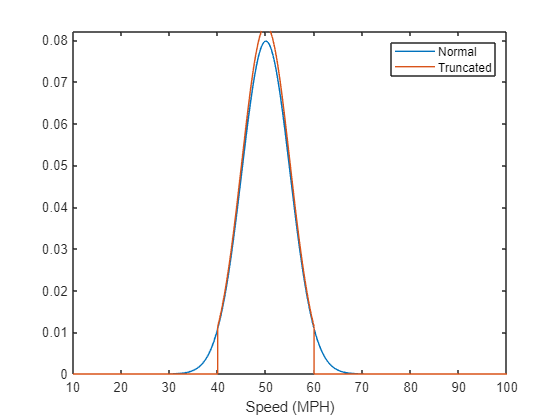

pd = makedist('Normal',50,5);
pd_trunc  = truncate(pd,40, 60);
fplot(@(x) pdf(pd,x),[10 100]);
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off
legend('Normal','Truncated')

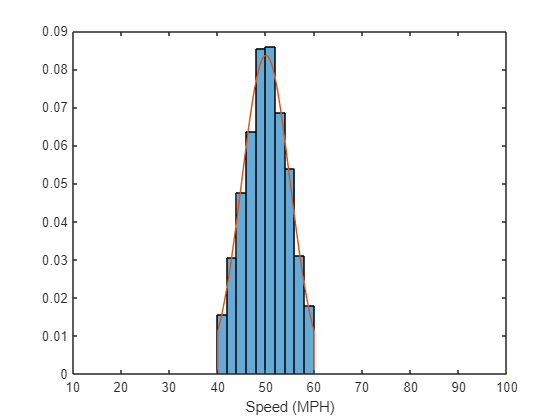

data = random(pd_trunc,[1000,1]);
histogram(data,'Normalization','pdf')
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off

**Result:**

% Output answers to Q1 and Q2
fprintf('(Q1) On average, does predictive routing save more than 5%% of the trip time to a 95%% confidence?');

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence?

fprintf('\tQ1: On average, predictive routing does%s save more than 5%% of the trip time to a 95% confidence.', Q1_predictive_routing_savings_value);

	Q1: On average, predictive routing does NOT save more than 5% of the trip time to a 95

fprintf('(Q2) What fraction of trips are re-routed due to road conditions?');

(Q2) What fraction of trips are re-routed due to road conditions?

fprintf('\tQ2: %0.4f%% of trips are re-routed due to road conditions.', Q2_fraction_of_trips_rereouted_value);

	Q2: 0.0000% of trips are re-routed due to road conditions.